addpath(genpath('./'));
close all;clc;clear;

## **Load the data and set the parameters**

% load MAT,set para
load('./Data/SPEN_2D_Q96_R2.mat');
mat=permute(SPEN_2D_Q96_R2,[1 3 2]);
SPENpara.infor.PEfov=240;
SPENpara.infor.PEoffset=0;
Q = 96;% time-bandwidth factor
SPENpara.recon.Q=Q;
SPENpara.recon.PEshiftnorm=0;
[Nx,Nc,Netl,Ns,Nseg,Nb]=size(mat);
ksp_spen=permute(reshape(permute(mat,[1 5 3 2 4 6]),[Nx Netl*Nseg Nc Ns Nb]),[2 1 3 4 5 6]);
disp('repermute data, done');

repermute data, done


% Get SPEN parameter
disp('Extracting SPEN reconstruction parameters');

Extracting SPEN reconstruction parameters


Nacq=size(ksp_spen,1);
Nfull=2*SPENpara.recon.Q;
Q=-SPENpara.recon.Q/(SPENpara.infor.PEfov)^2;
k_source=(-3*Nacq/2:3*Nacq/2-1)*1/SPENpara.infor.PEfov;
k_response=(-Nacq/2:Nacq/2-1)*Nfull/Nacq*1/SPENpara.infor.PEfov ;
dy = -SPENpara.infor.PEoffset*(2*pi);
A= A_k2k_shift(Q,k_source,k_response,dy);
disp('Extracting SPEN reconstruction parameters, done');

Extracting SPEN reconstruction parameters, done


## SPEN reconstruction: deconvolution image reconstruction protocols

disp('Doing SPEN reconstruction');

Doing SPEN reconstruction


Npe=size(ksp_spen,1);
% Referenceless reconstruction of spatiotemporally encoded imaging:we treat the even and odd data as two segmented k space to do their SPEN reconstructions and then 
%apply the phase differece to correct the even data, this is a special feature of referenceless even/odd correction in SPEN MRI, please refer to
%'https://pubmed.ncbi.nlm.nih.gov/24420445/'
Nseg =2;
A_ref=crop(A(1:Nseg:end,:),[Npe/Nseg Npe/Nseg]);
AHA=A_ref'*A_ref;
[~,S,~]=svd(AHA);
lambda=0.5*S(1,1);
AH_ref=pinv(AHA + lambda *eye(size(AHA)))*A_ref';   
%
dsize=size(ksp_spen);
dsize(1)=dsize(1)/Nseg;
ksp_ref=reshape(AH_ref*ksp_spen(1:Nseg:end,:),dsize);
im_ref=cifftn(ksp_ref,[1 2]);

ksp_spen_c=ksp_spen;
% the self-navigating even/odd compensation method
for m=2:Nseg
    A_currentseg=crop(A(m:Nseg:end,:),[Npe/Nseg Npe/Nseg]);

    ksp_currentseg=reshape(pinv(A_currentseg)*ksp_spen(m:Nseg:end,:),dsize);
    
    im_currentseg=cifftn(ksp_currentseg,[1 2]);
    im_phc=bsxfun(@times,sos(im_currentseg,3),exp(1i*angle(im_currentseg.*conj(im_ref))));
    ph_c=-angle(cifftn(bsxfun(@times,cfftn(im_phc,[1 2]),(hamming(Npe/Nseg)*hamming(Nx).').^2),[1 2]));
    im_currentseg_c=bsxfun(@times,im_currentseg,exp(1i*ph_c));
    ksp_currentseg_c=cfftn(im_currentseg_c,[1 2]);

ksp_spen_c(m:Nseg:end,:,:,:,:,:)=reshape(A_currentseg*ksp_currentseg_c(:,:),dsize);
end

A_rec=crop(A,[Npe,Npe]);
AHA=A_rec'*A_rec;
[~,S,~]=svd(AHA);
lambda=0.5*S(1,1);
A_inv=pinv(AHA + lambda *eye(size(AHA)))*A_rec';
dsize=size(ksp_spen);
ksp_rec_c=reshape(A_inv*ksp_spen_c(:,:),dsize);
ksp_rec_c=bsxfun(@times,ksp_rec_c,exp(1i*2*pi*SPENpara.recon.PEshiftnorm*(-Npe/2:(Npe/2-1))).');
im_rec_c=cifftn(ksp_rec_c,[1 2]);
disp('Doing SPEN reconstruction, done');

Doing SPEN reconstruction, done


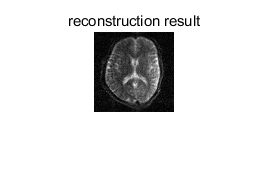

figure();imshow3(abs(permute(crop(im_rec_c,[80,80]),[2,1])));title('reconstruction result');

## optimization: aliasing effects removal in SPEN MRI: A k‐space perspective

refer to 'https://onlinelibrary.wiley.com/doi/full/10.1002/mrm.29638'

% simulicate the aliasing edge
ksp_rec_1=reshape(A_inv*A(:,1:Npe)*A_inv*ksp_spen_c(:,:),dsize);
ksp_rec_1=bsxfun(@times,ksp_rec_1,exp(1i*2*pi*SPENpara.recon.PEshiftnorm*(-Npe/2:(Npe/2-1))).');
im_h1 = squeeze(sos(cifftn(ksp_rec_1,[1,2]),3));
ksp_rec_3=reshape(A_inv*A(:,1+2*Npe:end)*A_inv*ksp_spen_c(:,:),dsize);
ksp_rec_3=bsxfun(@times,ksp_rec_3,exp(1i*2*pi*SPENpara.recon.PEshiftnorm*(-Npe/2:(Npe/2-1))).');
im_h3 = squeeze(sos(cifftn(ksp_rec_3,[1,2]),3));

diff = eye(Npe); diff = eye(Npe)-[diff(:,2:end),diff(:,1)];

gaussianFilter = fspecial('gaussian', [3, 3],5);
for r = 1:Ns
    edge(:,:,r) = abs(diff*im_h1(:,:,r))+abs(diff*im_h3(:,:,r));
    edge(:,:,r) = imfilter(edge(:,:,r), gaussianFilter, 'circular', 'conv');
end
edge = edge./max(edge,[],[1,2]);

disp('Doing edge detection, done');

Doing edge detection, done


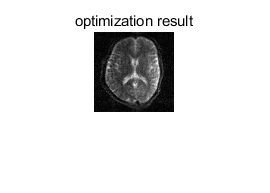


% remove the aliasing effects
pow =2;
weight =1e-3;
edge0 = 0.9*power(edge,pow); 
imopt = opt_process(im_rec_c,edge0,weight);

im_cc = permute(imopt,[2,1]);

figure();imshow3(abs(crop(im_cc,[80,80])));title('optimization result');

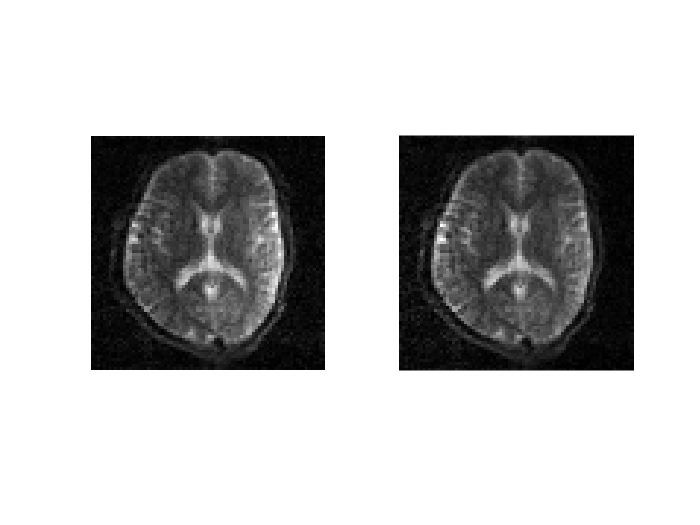



% intensity correct: Brightness correction in the PE direction of SPEN images.
im_cc2 = im_cc;
Ny=size(im_rec_c,2);
Intensity_PE_correction=exp(-1/1*(0:Ny-1)/Ny);
im_cc_r=bsxfun(@times,im_cc2,Intensity_PE_correction);
figure();
subplot(121);imshow3(abs(crop(im_cc2,[80,80])));
subplot(122);imshow3(abs(crop(im_cc_r,[80,80])));